# Sistemas de Control con Retardo Dominante

## Sobre el Autor...

Mi nombre es Sergio Andres Castaño Giraldo, soy ingeniero en Instrumentación y Control, tengo una maestría en automatización y sistemas de control y estoy finalizando mi doctorado en ingeniería química con enfasis a control avanzado.  Llevo más de 7 años enseñando y difundiendo temas sobre  control, modelado, automatización e instrumentación de procesos en mi sitio web **Control Automático Educación** y en mi canal de YouTube **Sergio A. Castaño Giraldo** el cual es el **mayor canal** de habla hispana sobre teoría de control.

### Links de Interés:

Sitio WEB: [https://controlautomaticoeducacion.com/](https://controlautomaticoeducacion.com/)

Canal de YouTube: [https://www.youtube.com/c/SergioACastañoGiraldo](https://www.youtube.com/c/SergioACastañoGiraldo)

Cursos de Simulink: [https://controlautomaticoeducacion.com/simulink/](https://controlautomaticoeducacion.com/simulink/)

Curso de Instrumentación: [https://controlautomaticoeducacion.com/instrumentacion-2/](https://controlautomaticoeducacion.com/instrumentacion-2/)

Cursos de Control en Sistemas Embebidos: [https://controlautomaticoeducacion.com/sistemas-de-control-en-dispositivos-embebidos/](https://controlautomaticoeducacion.com/sistemas-de-control-en-dispositivos-embebidos/)

## Control de Procesos con Retardo Dominante

La mayoría de los procesos industriales presentan retardos en sus dinámicas. Ejemplos típicos de la industria de procesos son las columnas de destilación, los evaporadores y los intercambiadores de calor. El retardo es un fenómeno resultante del desplazamiento temporal que puede presentarse entre dos o más variables del sistema de control. Puede ser causado, por ejemplo, por el tiempo requerido para transportar masa, energía o información.

## Sistema Monovariable - SISO

Diseñar un control PI convencional por cualquier estrategia del siguiente proceso representado por una función de transferencia de primer orden


$$G_1 \left(s\right)=\frac{0\ldotp 5}{12s+1}$$


clc
clear


Sin modificar la sintonia del controlador anterior, adicionar un pequeño retardo de tiempo al sistema y analizar que sucede.


$$G_2 \left(s\right)=\frac{0\ldotp 5}{12s+1}e^{-10s}$$


Analizar el lugar de las raíces del proceso aproximando el retaro con un Padé


%rlocus sistema sin retardo

%rlocus sistema con retardo


Verificar el comportamiento del sistema si se deja por fuera el retardo de transporte del lazo cerrado de control

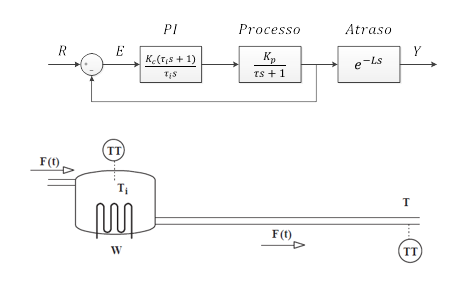

## Predictor de Smith

Diseñar un predictor de Smith para el proceso con retardo dominante empleando el Simulink y observe el comportamiento de la variable controlada.

## Predictor de Smith Filtrado

Diseñar un predictor de Smith filtrado considerando un filtro de segundo orden donde se cancele la dinámica de lazo cerrado. Mas detalles pueden ser vistos en: [https://controlautomaticoeducacion.com/control-realimentado/predictor-de-smith-filtrado/](https://controlautomaticoeducacion.com/control-realimentado/predictor-de-smith-filtrado/)


$$
F_r(s)=\frac{(T_{r}s+1)(\beta s+1)}{(T_fs+1)^2}$$


%% Filtro de Robustez


## Programar un Sistema Multivariable MIMO con Multiples Retardos

La columna de destilación de Wood and Berry separa metanol y agua, con dos variables de salida ($y_1$,  $y_2$, fracción molar de metanol en el topo y en el fondo respectivamente), dos variables de entrada ($u_1$, reflujo en el topo y , flujo del rehervidor $u_2$) 


$$P\left( s \right) = \left[ {\begin{array}{*{20}{c}} {\frac{{12.8e^{-s}}}{{16.7s + 1}}}&{\frac{{ - 18.9{e^{ - 3s}}}}{{21s + 1}}}\\ {\frac{{6.6{e^{ - 7s}}}}{{10.9s + 1}}}&{\frac{{ - 19.4{e^{ - 3s}}}}{{14.4s + 1}}} \end{array}} \right]$$


Calculo de la matriz RGA 

Diseñe un controlador primario para la estructura del predictor de Smith. Para este ejemplo será diseñado un controlador por Ziegler Nichols - Método 2 de Lazo Cerrado: [https://controlautomaticoeducacion.com/control-realimentado/ziegler-nichols-sintonia-de-control-pid/](https://controlautomaticoeducacion.com/control-realimentado/ziegler-nichols-sintonia-de-control-pid/)

Diseño del Desacoplador

syms s;  %Define a variavel simbolica s


Diseñar el Filtro de Robustez

%% Filtro de Robustez


## Control Predictivo MPC

Otra forma de poder controlar sistemas con retardo dominante es empleando un controlador avanzado como el MPC (Model Predictive Control)

[https://www.youtube.com/watch?v=cTdvAor2kNQ&list=PLF-qcfymUY4U8heDB4TqzPUHUs-PaN2EM&index=1](https://www.youtube.com/watch?v=cTdvAor2kNQ&list=PLF-qcfymUY4U8heDB4TqzPUHUs-PaN2EM&index=1)

Utilizar el Toolbox de Simulink y crear un controlador MPC para la columna de destilación de Wood and Berry.